Import functions

addpath('C:\Users\js1771\OneDrive - University of York\Documents\Work related\PhD stuff\IO modelling\IO Toy Model Practice\');

## Set up Toy Model

Create:

- Inter industry flows, Z matrix 

- Final demand, f vector

- Total output, x vector 

- Technical coefficients, a matrix

- Leontieff inverse, L matrix 

- environmental coefficients, e

- environmental damage, d

Z = [100 300 250; 200 100 75; 30 300 275];

f = [200; 150 ;175];

x = Z*ones(size(Z,1),1) + f; 

a = Z/diag(x);

L = leontieffInverse(a);

e = [2; 4; 0.5];

d = x .* e;

## Scenario 1.1 Project IO table into the future assuming fixed GDP growth 

- Set GDP growth, delta

- Set GDP elasticity of final demand, epsilon

delta = 3;
epsilon = [0.5; 1.1; 1];
sectoralGrowthPerc = epsilon * delta;

Project final demand, f and total output x, into the future to the year 2050

yr = 2025

yr = 2025

endYear = 2030

endYear = 2030

  
for i = 1:(endYear-yr)
    
    f(:,i+1) = f(:,i) .* (1+(sectoralGrowthPerc/100));
    x(:,i+1) = L*f(:,i+1);

end 

Calculate total output and final demand for each year

Plot results

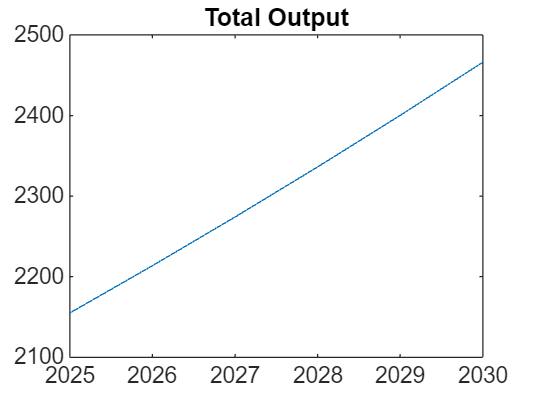

totalOutput = ones(1,3)* x;
totalFinalDemand = ones(1,3)*f;

plot(2025:2030, totalOutput);
title('Total Output')

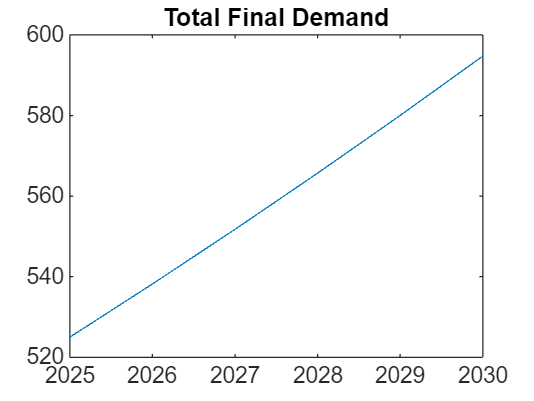


plot(2025:2030,totalFinalDemand);
title('Total Final Demand')

## Scenario 1.2 Project IO table into the future assuming GDP growth + random term

- Set GDP growth, delta

- Set GDP elasticity of final demand, epsilon

delta = 3;
epsilon = [0.5; 1.1; 1];
sectoralGrowthPerc = epsilon * delta;

Project final demand, f and total output x, into the future to the year 2050

yr = 2025;
endYear = 2050;
  
for i = 1:(endYear-yr)
    rdm = rand(1);
    f(:,i+1) = f(:,i) .* (1+((sectoralGrowthPerc*rdm)/100));
    x(:,i+1) = L*f(:,i+1);

end 

Calculate total output and final demand for each year

Plot result

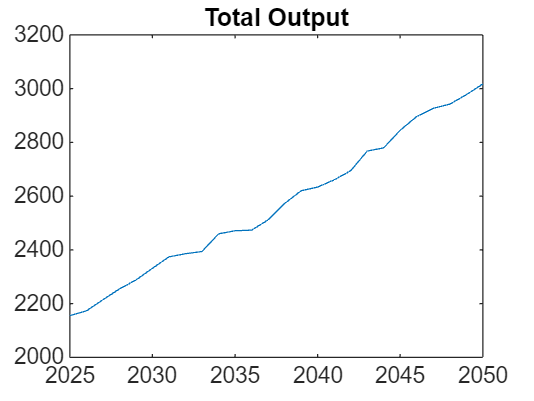

totalOutput = ones(1,3)* x;
totalFinalDemand = ones(1,3)*f;

plot(2025:2050, totalOutput)
title('Total Output')

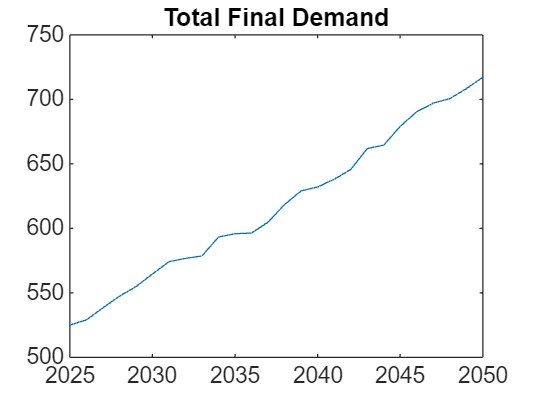


plot(2025:2050,totalFinalDemand)
title('Total Final Demand')

## Scenario 2.1 Project IO table into the future with multiple factors changing over time

Description: Investment, drives GDP change which in turn drives final demand changes. Investment also reduces values in the technical coefficient matric a, and the environmental coefficients, e, representing 'technological improvement'.


$$\Delta \textrm{GDP}=\alpha I$$



$$f_{t+1} =f_t \Delta \textrm{GDP}\epsilon$$
     


$$a=a\;\left(1-\beta I\right)$$



$$e=e\left(1-\theta I\right)$$


where:

- Investment, I

- GDP response to investment (elasticity), alpha

- Final demand sectors response to GDP change (elasticity), epsilon

- Technology improvement coefficient, beta 

- Environmental technology improvement coefficient, theta

I = 17.9;
alpha = 0.25;
GDP = alpha*I;

epsilon = [0.5; 1.1; 1];

beta = 0.1;
theta = 0.05;

Project investment, I, GDP change, delta, final demand, f, technical coefficient matrix, a, total output x, and environmental damage, d, into the future to the year 2050

yr = 2025;
endYear = 2050;
period = endYear-yr;
a_series = zeros([size(a), period]);
a_series(:,:,1) = a;


for i = 1:(period)
    
    % add a random term to investment 
    I_rdm = randi([-5 5],1);
    I_new = I + I_rdm;
    
    GDP(i+1) = I_new * alpha ;
    sectoralGrowthPerc = epsilon * GDP(i+1);

    f(:,i+1) = f(:,i) .* (1+((sectoralGrowthPerc)/100));

    a_series(:,:,i+1) = a_series(:,:,i)*(1-(beta*(I_new/100)));
    L = leontieffInverse(a_series(:,:,i+1));
    x(:,i+1) = L*f(:,i+1);
    d(:,i+1) = x(:,i+1) .* e;

    I = I_new;

end 

Calculate total output and final demand for each year

Plot result

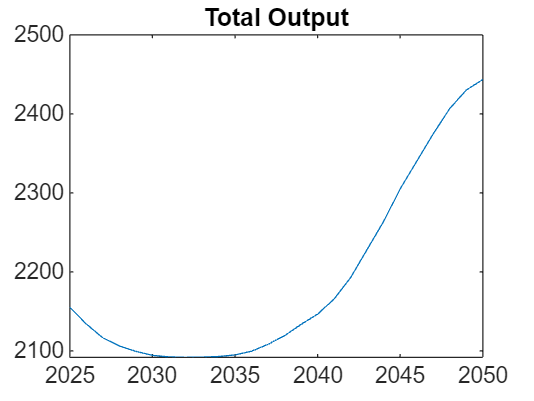

totalOutput = ones(1,3)* x;
totalFinalDemand = ones(1,3)*f;
totalEnvironmentalDamage = ones(1,3)*d;

plot(2025:2050, totalOutput)
title('Total Output')

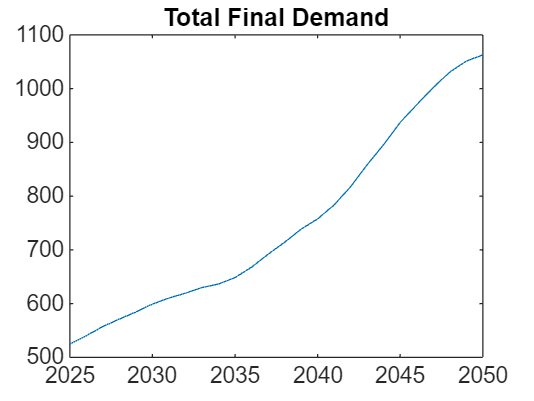


plot(2025:2050,totalFinalDemand)
title('Total Final Demand')

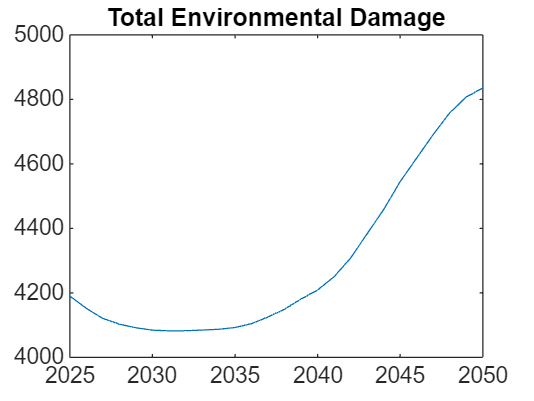


plot(2025:2050,totalEnvironmentalDamage)
title('Total Environmental Damage')